## Задание 6. Задача слежения за гармоническим сигналом (регулятор общего вида)

## Гармонический сигнал - режим работы

simTimeStart = 0;
simTimeEnd = 30;
step = 0.002;
data.time=(simTimeStart:step:simTimeEnd)';
modelName = 'task6'; 

V = 2;
input = 2*sin(0.5*data.time);
data.signals(1).values = input;
data.signals(1).dimensions = 1;

### Испытания - какие-то 3 штуки

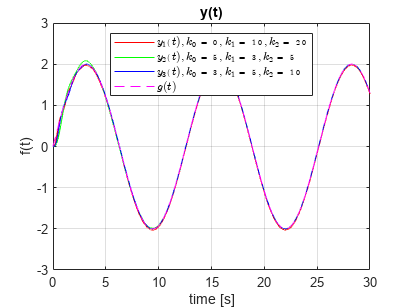

load_system(modelName);
k2 = 20; k1 = 10; k0 = 0;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
k2 = 5; k1 = 3; k0 = 5;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
k2 = 10; k1 = 5; k0 = 3;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

%%%    y(t)   %%%
figure;
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, 2*sin(0.5 * time), 'magenta--');
title('y(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_0 = 0, k_1 = 10, k_2 = 20$','$y_2(t), k_0 = 5, k_1 = 3, k_2 = 5$','$y_3(t), k_0 = 3, k_1 = 5, k_2 = 10$', '$g(t)$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task6_exp1')

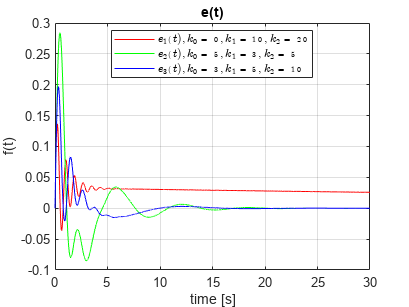


%%%    e(t)   %%%
figure;
plot(time, 2*sin(0.5 * time) - y_out1, 'r');
hold on;
plot(time, 2*sin(0.5 * time) - y_out2, 'g');
hold on;
plot(time, 2*sin(0.5 * time) - y_out3, 'b');
title('e(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_0 = 0, k_1 = 10, k_2 = 20$','$e_2(t), k_0 = 5, k_1 = 3, k_2 = 5$','$e_3(t), k_0 = 3, k_1 = 5, k_2 = 10$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task6_exp2')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab4\latex4\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end